EE583 HW1

Eda Özkaynar - 2375582

**Question 1**

load fisheriris
X = meas(:,1:2);
y = categorical(species);
labels = categories(y);

Visualize the data

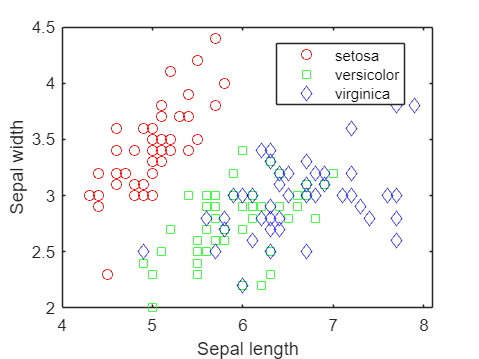

gscatter(X(:,1),X(:,2),species,'rgb','osd');
xlabel('Sepal length');
ylabel('Sepal width');

Classifiers

classifier_name = {'Naive Bayes','Discriminant Analysis','Classification Tree','Nearest Neighbor'};
classifier{1} = fitcnb(X,y);
classifier{2} = fitcdiscr(X,y);
classifier{3} = fitctree(X,y);
classifier{4} = fitcknn(X,y);

Predict and Plot

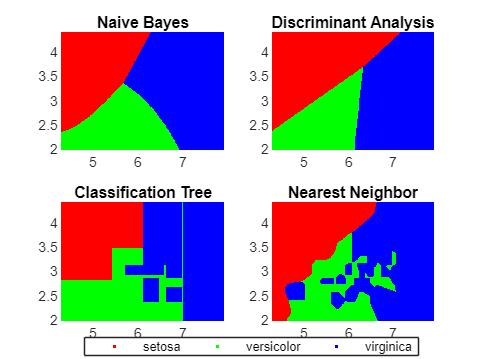

x1range = min(X(:,1)):.01:max(X(:,1));
x2range = min(X(:,2)):.01:max(X(:,2));
[xx1, xx2] = meshgrid(x1range,x2range);
XGrid = [xx1(:) xx2(:)];
for i = 1:numel(classifier)
   predictedspecies = predict(classifier{i},XGrid);

   subplot(2,2,i);
   gscatter(xx1(:), xx2(:), predictedspecies,'rgb');

   title(classifier_name{i})
   legend off, axis tight
end

legend(labels,'Location',[0.35,0.01,0.35,0.05],'Orientation','Horizontal')

**Question 2**

load fisheriris
X = meas(:,1:2);
Y = species;
labels = unique(Y);

Train a naive Bayes classifier.

mdl = fitcnb(X,Y);

Change Prior

mdl.Prior = [0.2 0.1 0.7]

mdl =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {3×2 cell}


  Properties, Methods


[xx1, xx2] = meshgrid(4:.01:8,2:.01:4.5);
XGrid = [xx1(:) xx2(:)];

Prediction

[predictedspecies,Posterior,~] = predict(mdl,XGrid);

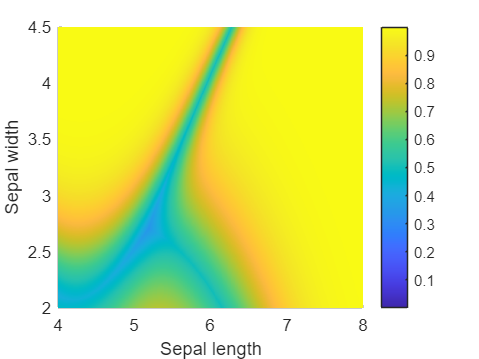

sz = size(xx1);
s = max(Posterior,[],2);

figure
hold on
surf(xx1,xx2,reshape(Posterior(:,1),sz),'EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,2),sz),'EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,3),sz),'EdgeColor','none')
xlabel('Sepal length');
ylabel('Sepal width');
colorbar
view(2) 
hold off

Prediction

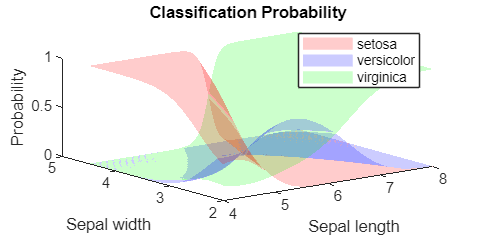

[predictedspecies,Posterior,~] = predict(mdl,XGrid);

figure('Units','Normalized','Position',[0.25,0.55,0.4,0.35]);
hold on
surf(xx1,xx2,reshape(Posterior(:,1),sz),'FaceColor','red','EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,2),sz),'FaceColor','blue','EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,3),sz),'FaceColor','green','EdgeColor','none')
xlabel('Sepal length');
ylabel('Sepal width');
zlabel('Probability');
legend(labels)
title('Classification Probability')
alpha(0.2)
view(3)
hold off

**Question 3 : Mahalanobis**

Generate a correlated bivariate sample data set.

rng('default') % For reproducibility
X = mvnrnd([0;0],[1 .9;.9 1],1000);

Specify four observations that are equidistant from the mean of `X` in Euclidean distance.

Y = [1 1;1 -1;-1 1;-1 -1];

Compute the Mahalanobis distance of each observation in `Y` to the reference samples in `X`.

d2_mahal = mahal(Y,X)

d2_mahal =     1.1095
   20.3632
   19.5939
    1.0137


Compute the squared Euclidean distance of each observation in `Y` from the mean of `X`.

d2_Euclidean = sum((Y-mean(X)).^2,2)

d2_Euclidean =     2.0931
    2.0399
    1.9625
    1.9094


Plot `X` and `Y` by using [`scatter`](https://www.mathworks.com/help/matlab/ref/scatter.html) and use marker color to visualize the Mahalanobis distance of `Y` to the reference samples in `X`.

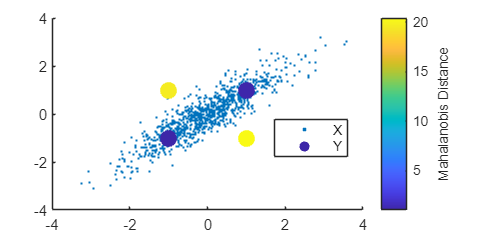

scatter(X(:,1),X(:,2),10,'.') % Scatter plot with points of size 10
hold on
scatter(Y(:,1),Y(:,2),100,d2_mahal,'o','filled')
hb = colorbar;
ylabel(hb,'Mahalanobis Distance')
legend('X','Y','Location','best')
hold off

Plot fcountour

[xx1, xx2] = meshgrid(linspace(-10, 10, 100), linspace(-10, 10, 100));
XGrid = [xx1(:) xx2(:)];

Cov_M1 = [1 0; 0 1];
Cov_M2 = [1 0.5; 0.5 1];
Cov_M3 = [1 -0.7; -0.7 1];

mu1    = [3;3];
mu2    = [0;0];
mu3    = [-2;-2];

X1 = mvnrnd(mu1,Cov_M1,100);
X2 = mvnrnd(mu2,Cov_M2,100);
X3 = mvnrnd(mu3,Cov_M3,100);

abs_mahal1 = abs(mahal(XGrid, X1) - mahal(XGrid, X2));
abs_mahal2 = abs(mahal(XGrid, X1) - mahal(XGrid, X3));

f_0 = @(x1,x2) abs(mahal([x1 x2],X));
f_1 = @(x1,x2) abs(mahal([x1 x2],X1));
f_2 = @(x1,x2) abs(mahal([x1 x2],X2));
f_3 = @(x1,x2) abs(mahal([x1 x2],X3));



scatter(X1(:,1),X1(:,2),10,'.')
hold on
fcontour(f_1,'LevelList',[1,3,5,7,9])

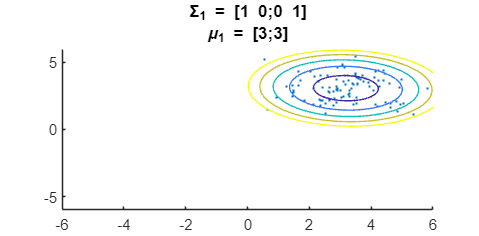

hold off
title({['{\Sigma}_1 = ',mat2str(Cov_M1)],['{\mu}_1 = ',mat2str(mu1)]})


scatter(X2(:,1),X2(:,2),10,'.')
hold on
fcontour(f_2,'LevelList',[1,3,5,7,9])

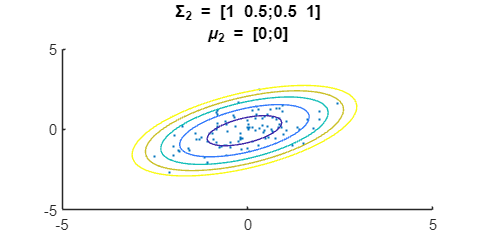

hold off
title({['{\Sigma}_2 = ',mat2str(Cov_M2)],['{\mu}_2 = ',mat2str(mu2)]})



scatter(X3(:,1),X3(:,2),10,'.')
hold on
fcontour(f_3,'LevelList',[1,3,5,7,9])

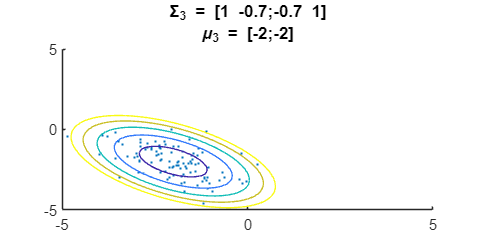

hold off
title({['{\Sigma}_3 = ',mat2str(Cov_M3)],['{\mu}_3 = ',mat2str(mu3)]})




figure;
scatter(XGrid(:,1),XGrid(:,2),100,abs_mahal1,'filled')
hb = colorbar;
ylabel(hb,'Mahalanobis Distance')
hold on
fcontour(f_1,[-10 10 -10 10],'LineColor','green','LevelList',1:2:20)

hold on
fcontour(f_2,[-10 10 -10 10],'LineColor','green','LevelList',1:2:20)

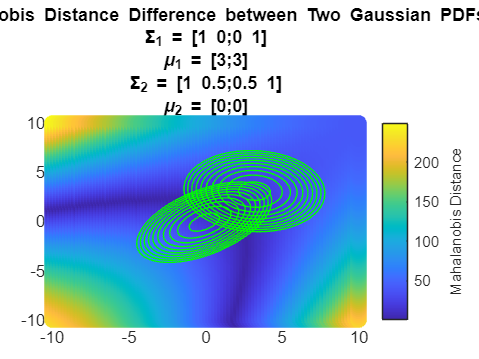

hold off
title({'Mahalanobis Distance Difference between Two Gaussian PDFs',['{\Sigma}_1 = ',mat2str(Cov_M1)],['{\mu}_1 = ',mat2str(mu1)],['{\Sigma}_2 = ',mat2str(Cov_M2)],['{\mu}_2 = ',mat2str(mu2)]})


figure;
scatter(XGrid(:,1),XGrid(:,2),100,abs_mahal2,'filled')
hb = colorbar;
ylabel(hb,'Mahalanobis Distance')
title('Mahalanobis Distance Difference between Two Gaussian PDFs');
hold on
fcontour(f_1,[-10 10 -10 10],'LineColor','green','LevelList',1:2:20)

hold on
fcontour(f_3,[-10 10 -10 10],'LineColor','green','LevelList',1:2:20)

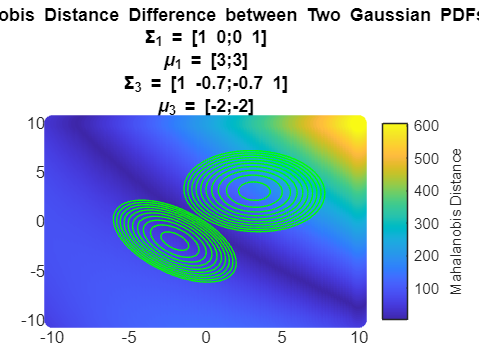

hold off
title({'Mahalanobis Distance Difference between Two Gaussian PDFs',['{\Sigma}_1 = ',mat2str(Cov_M1)],['{\mu}_1 = ',mat2str(mu1)],['{\Sigma}_3 = ',mat2str(Cov_M3)],['{\mu}_3 = ',mat2str(mu3)]})

**Question 4**

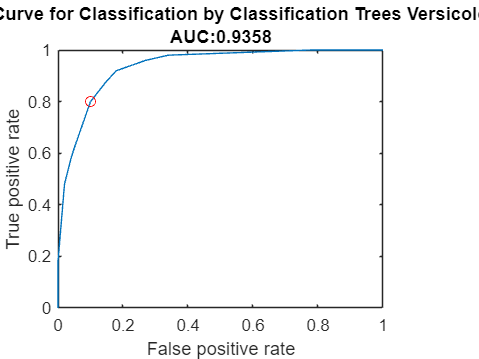

load fisheriris
% Train a classification tree
Model = fitctree(meas(:,1:2),species, ...
    'ClassNames',{'setosa','versicolor','virginica'});
% Predict the class labels and scores
[~,score] = resubPredict(Model);

% The scores are the posterior probabilities that an observation
diffscore1 = score(:,2) - max(score(:,1),score(:,3));
diffscore2 = score(:,1) - max(score(:,2),score(:,3));
diffscore3 = score(:,3) - max(score(:,1),score(:,2));

[X1,Y1,T1,AUC_versi,OPTROCPT1,suby,subnames] = perfcurve(species,diffscore1,'versicolor');
plot(X1,Y1)
hold on
plot(OPTROCPT1(1),OPTROCPT1(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title({'ROC Curve for Classification by Classification Trees Versicolor',['AUC:', num2str(AUC_versi)]})
hold off

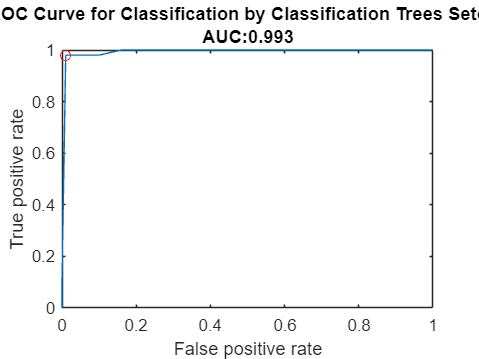


[X2,Y2,T2,AUC_setosa,OPTROCPT2,suby,subnames] = perfcurve(species,diffscore2,'setosa');
plot(X2,Y2)
hold on
plot(OPTROCPT2(1),OPTROCPT2(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title({'ROC Curve for Classification by Classification Trees Setosa',['AUC:', num2str(AUC_setosa)]})
hold off

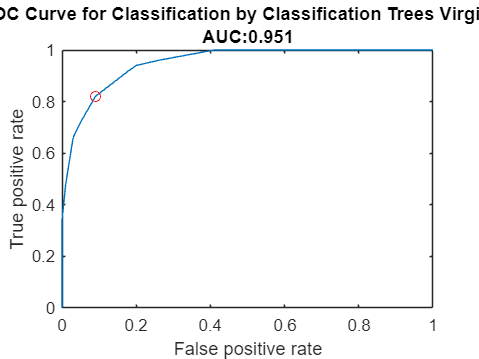


[X3,Y3,T3,AUC_virginica,OPTROCPT3,suby,subnames] = perfcurve(species,diffscore3,'virginica');
plot(X3,Y3)
hold on
plot(OPTROCPT3(1),OPTROCPT3(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title({'ROC Curve for Classification by Classification Trees Virginica',['AUC:', num2str(AUC_virginica)]})
hold off

T1((X1==OPTROCPT1(1))&(Y1==OPTROCPT1(2)))

ans = 0.2857

T2((X2==OPTROCPT2(1))&(Y2==OPTROCPT2(2)))

ans = 0.9556

T3((X3==OPTROCPT3(1))&(Y3==OPTROCPT3(2)))

ans = 0.1111

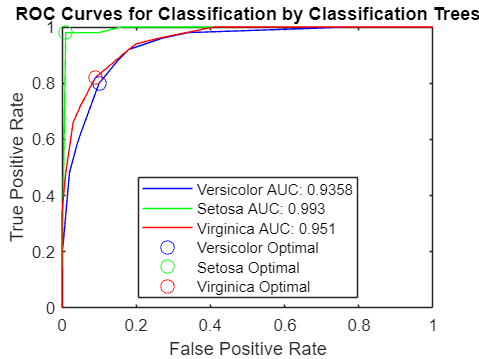

% Plotting all ROC curves in one figure
figure
plot(X1, Y1, 'b', 'DisplayName', ['Versicolor AUC: ', num2str(AUC_versi)]);
hold on
plot(X2, Y2, 'g', 'DisplayName', ['Setosa AUC: ', num2str(AUC_setosa)]);
plot(X3, Y3, 'r', 'DisplayName', ['Virginica AUC: ', num2str(AUC_virginica)]);

% Plot optimal ROC points
plot(OPTROCPT1(1), OPTROCPT1(2), 'bo', 'MarkerSize', 8, 'DisplayName', 'Versicolor Optimal');
plot(OPTROCPT2(1), OPTROCPT2(2), 'go', 'MarkerSize', 8, 'DisplayName', 'Setosa Optimal');
plot(OPTROCPT3(1), OPTROCPT3(2), 'ro', 'MarkerSize', 8, 'DisplayName', 'Virginica Optimal');

% Formatting the plot
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for Classification by Classification Trees');
legend('Location', 'Best');
hold off

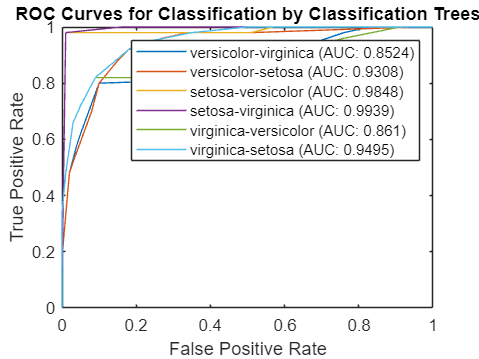

diffscore23 = score(:,2) - score(:,3);
diffscore21 = score(:,2) - score(:,1);
diffscore12 = score(:,1) - score(:,2);
diffscore13 = score(:,1) - score(:,3);
diffscore32 = score(:,3) - score(:,2);
diffscore31 = score(:,3) - score(:,1);

% Compute ROC curves and AUC for each diffscore
[X1, Y1, ~, AUC1] = perfcurve(species, diffscore23, 'versicolor');
[X2, Y2, ~, AUC2] = perfcurve(species, diffscore21, 'versicolor');
[X3, Y3, ~, AUC3] = perfcurve(species, diffscore12, 'setosa');
[X4, Y4, ~, AUC4] = perfcurve(species, diffscore13, 'setosa');
[X5, Y5, ~, AUC5] = perfcurve(species, diffscore32, 'virginica');
[X6, Y6, ~, AUC6] = perfcurve(species, diffscore31, 'virginica');

% Plot the ROC curves for each diffscore
plot(X1, Y1)
hold on
plot(X2, Y2)
plot(X3, Y3)
plot(X4, Y4)
plot(X5, Y5)
plot(X6, Y6)

% Add AUC values to the legend
legend(['versicolor-virginica (AUC: ' num2str(AUC1) ')'], ...
       ['versicolor-setosa (AUC: ' num2str(AUC2) ')'], ...
       ['setosa-versicolor (AUC: ' num2str(AUC3) ')'], ...
       ['setosa-virginica (AUC: ' num2str(AUC4) ')'], ...
       ['virginica-versicolor (AUC: ' num2str(AUC5) ')'], ...
       ['virginica-setosa (AUC: ' num2str(AUC6) ')'])

% Add labels and title
xlabel('False Positive Rate')
ylabel('True Positive Rate')
title('ROC Curves for Classification by Classification Trees')

% Release the hold on the plot
hold off